# Seminar 4 - ARX

**Authors:** prof. Ing. Vladimír Havlena, CSc., Ing. David Vošahlík

## Introduction

The Auto Regressive model with eXternal input (ARX) is used for parameter estimation of a dynamical model, where the parameters are not known. This grey box approach can be used in many scenarios. Imagine that you have a model from known physical first principles and you want to estimate its parameters from measured data. Another example is if you have time varying (slowly) parameters and you want to reflect that in your controller. 

## ARX Batch identification

In this section the estimation from measured data will be executed in a batch. In this case the ARX parameter estimation is linear regression. In this section we will inspect a model of a linearized chemical process that is described by a transfer function:


$$H\left(s\right)=\frac{{b_0 s}^2 +b_1 s+b_2 }{{{s^3 \;+\;a}_1 s}^2 +a_2 s+a_3 }$$


- Discretize the system using the sampling time $T_s =0\ldotp 2s$

- Generate experiment data also with measurement noise (do not forget about noise shaping)

- Construct the regressor and do the parameters estimate

- Compare the values of the parameters with the real ones that were used to generate the data

- change sample size and check the estimation performance

- use both algorithms for parameter estimation - QR decompozition and pseudoinverse

- Change the parameters of the estimation algorithm and observe the behavior:

- ARX model structure - change the *na* and *nb* values

- number of samples

- noise variance

- feed the system with unit step. Will it be possible to do the batch estimate using this input?

For this task modify the prepared function *ARXBatch *that is in Appendix

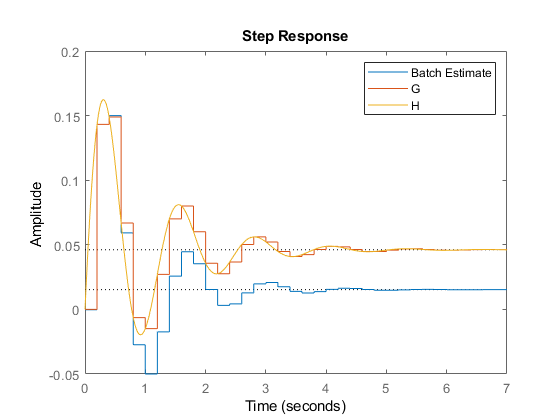

%% ARX Batch parameter identification

ARXBatch('plot', 1, 'na', 3, 'nb', 3, 'n_samples',10000);

### Estimated model quality

Here your task will be to evaluate the estimated batch model quality using the residual sum of squares. Your task will be to:

- Set different model structures and compare the estimated noise variance. Don't forget to use only proper transfer function.

- What model structure would you use for real time implementation?

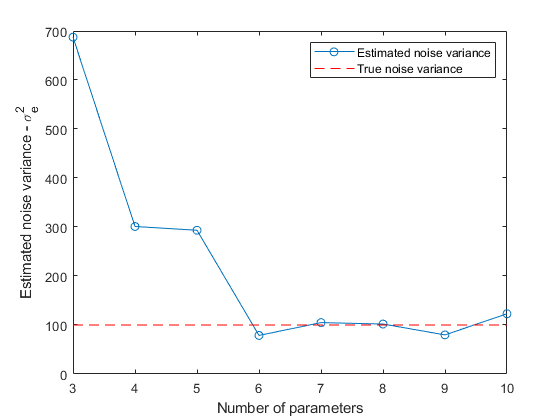

sigmaEst = nan(10,1);
for i = 2:5
    for j = 1:5
        if i >= j
            [Y, Z, theta] = ARXBatch('na', i, 'nb', j);
            sEst = 1/(numel(Y) - i - j)*(Y - Z*theta)'*(Y - Z*theta);
            sigmaEst(i + j) = min(sigmaEst(i + j), sEst);
        end
    end
end
figure;
plot(sigmaEst, '-o');
hold on;
line([3 10], [100 100], 'Color','red','LineStyle','--');
legend('Estimated noise variance', 'True noise variance')
ylabel('Estimated noise variance - \sigma_e^2');
xlabel('Number of parameters');

## ARX Recursive identification

Recursive least squares estimate for ARX model structure will be excercised in this section. Here your will be using the same system as described above and your task will be:

- Discretize the system using the sampling time $T_s =0\ldotp 2s$

- Generate experiment data with parameter change during the simulation time.

- Generate experiment data also with noise according to ARX model (do not forget about noise shaping).

- Implement the recursive estimation algorithm.

- Remind yourself of the forgetting. Why is it used?

- implement different types of forgetting - linear, exponential and if the time remains also try restricted forgetting either linear or exponential.

- Change the parameters of the estimation algorithm and observe the behavior:

- ARX model structure - change the *na* and *nb* values

- number of samples

- noise variance

You can also warm start the algorithm with batch estimate from few first samples.

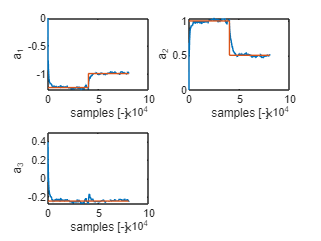

% Generate the data


n_samplesBatch = 30;
[Y, ~, theta_batch, P] = ARXBatch('n_samples', n_samplesBatch);

a_old = [1.0000   -1.2526    0.9958   -0.2466];
a_new = [1.0000   -1    0.5   -0.2466];
a = a_old;
b = [0.1432   -0.1737    0.0534];
na = numel(a) - 1;
nb = numel(b);
sig = 10;
f = @(z, a, b) a(2:end)*z(1:na) + b*z(na + 1:end) + sig*randn();
n_samples = [40000; 40000];
y = zeros(sum(n_samples), 1);
y(4:n_samplesBatch) = Y;
u = 150.*randn(sum(n_samples), 1);
theta = zeros(na + nb, sum(n_samples));
theta(:, n_samplesBatch) = theta_batch;
for i = n_samplesBatch + 1:sum(n_samples)
    if i > n_samples(1)
        a = a_new;
    end
    % Regresor construction
    z = [-y(i - 1:-1:i-na); u(i:-1:i-nb + 1)];
    y(i) = f(z, a, b);
    
    

    % Zeta
    zeta = z'*P*z;
    
    % Prediction error
    epsilon = y(i) - z'*theta(:, i-1);
    
    % Kalman gain
    K = P*z/(1+zeta);
    
    %%  Filtering (Data) step:
    %   Mean value update
    theta(:,i) = theta(:,i-1) + K*epsilon;
    
    %   Covariance update
    P = P - P*z*z'*P/(1+zeta);
    
    P_data_step = P;
    
    %%  Propagation (Time) step:
    %   mean value parameter estimation does not change
    %       theta(t+1|t) = theta(t|t)
    %
    %   updating the covariance matrix
    
    %%%  No forgetting
    %     P = P;
    
    %%%  Linear forgetting
%         V = 0.000001*eye(na + nb);
%         P = P + V;
%     
    %%%  Exponential forgetting
        tef = 1500;
        phi=1-1/tef;
        P=1/phi*P;
    
    %%%  Restricted linear forgetting
%         K = P*z;
%         V = 0.0001*eye(numVariables);
%         zeta_v = z'*V*z;
%         Vo = K*(zeta_v/zeta^2)*K';
%         P = P + Vo;
    
    %%%  Restricted exponential forgetting
%         K = P*z;
%         tef = 250;
%         fi=1-1/tef;
%         zeta_v = (1-fi)/fi * zeta;
%         Vo = K*(zeta_v/zeta^2)*K';
%         P = P + Vo;
    
    P_time_step = P;
end

% Plots of the estimates and true values
subplot(221);
plot(theta(1,:));
hold on
ind = 2;
plot([0, n_samples(1), n_samples(1), sum(n_samples)], [a_old(ind), a_old(ind), a_new(ind), a_new(ind)])
xlabel('samples [-]');
ylabel('a_1');

subplot(222);
plot(theta(2,:));
hold on
ind = 3;
plot([0, n_samples(1), n_samples(1), sum(n_samples)], [a_old(ind), a_old(ind), a_new(ind), a_new(ind)])
xlabel('samples [-]');
ylabel('a_2');

subplot(223);
plot(theta(3,:));
hold on
ind = 4;
plot([0, n_samples(1), n_samples(1), sum(n_samples)], [a_old(ind), a_old(ind), a_new(ind), a_new(ind)])
xlabel('samples [-]');
ylabel('a_3');

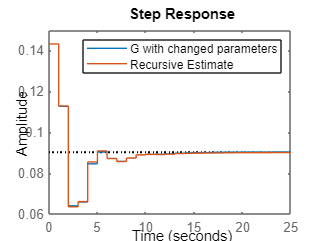


G_recursive = tf(theta(na+1:end, end)',[1 theta(1:na, end)'],1,'Variable','z^-1');
G_recursive.Name = 'Recursive Estimate';
figure;
G_new = tf(b,a_new,1,'Variable','z^-1');
G_new.Name = 'G with changed parameters';
step(G_new);
hold on;
step(G_recursive)
legend show

fix_ylim = ylim;

## Appendix

function [Y, Z, theta, P] = ARXBatch(varargin)
% You can enforce the estimated model structure with the arguments
% First argument sets the number of parameters in denominator of the TF
% Second argument sets the number of parameters in numerator of the TF


p = inputParser;
addParameter(p,'na',3, @isnumeric);
addParameter(p,'nb',3, @isnumeric);
addParameter(p,'plot',0, @isnumeric);
addParameter(p,'n_samples',100, @isnumeric);
parse(p, varargin{:});
na = p.Results.na;
nb = p.Results.nb;
plot = p.Results.plot;
n_samples = p.Results.n_samples;

[u, y, Ts, G, H] = generate_data(n_samples);





% Output vector
Y=y(1 + max(na,nb):n_samples);

% Regressor
Z=zeros(n_samples - max(na,nb),na+nb);

for i=1 + max(na,nb):size(Z,1) + max(na,nb)
    Z(i - max(na,nb),:)=[-y(i - 1:-1:i-na)', u(i:-1:i-nb + 1)];
end


% Batch identification (least squares)
% theta_batch = pinv(Z)*Y
% badly conditioned formula
theta_batch = (Z'*Z)\Z'*Y;
P_batch = inv(Z'*Z);
% QR algorithm solution
[Q,R] = qr(Z);
theta_batch = R\Q'*Y;
P_batch = inv(R'*R);

theta = theta_batch;
P = P_batch;
if plot
    % Plot result
    G_batch = tf(theta_batch(na+1:end)',[1 theta_batch(1:na)'],Ts,'Variable','z^-1');
    G_batch.Name = 'Batch Estimate';
    figure;
    step(G_batch)
    hold on;
    step(G)
    step(H)
    legend show
    fix_ylim = ylim;
end
end

function [u, y, Ts, G, H] = generate_data(n_samples)
a = [1     7    36   130];
b = [1     5     6];

Ts = 0.2;
H = tf(b, a);
G = c2d(H, Ts);                         % deterministic transfer function
He = tf(1, G.den{1}, Ts);               % noise transfer function

% generate input data and simulate the system
sig = 10;
u = 150.*randn(1,n_samples);
y = lsim(G, u, cumsum(Ts*ones(1, n_samples)) - Ts) + lsim(He, sig.*randn(n_samples, 1), cumsum(Ts*ones(1, n_samples)) - Ts);
end